Mp = 0.12;
zeta = -log(Mp)/(sqrt(pi^2 + log(Mp)^2))

zeta = 0.5594

ts = 180;
Wn = 4/(ts*zeta)

Wn = 0.0397

beta = acos(zeta);
beta = rad2deg(beta);
xpoint = -zeta*Wn

xpoint = -0.0222

tan_beta = tan((beta*pi)/180);
ypoint = tan_beta*zeta*Wn

ypoint = 0.0329

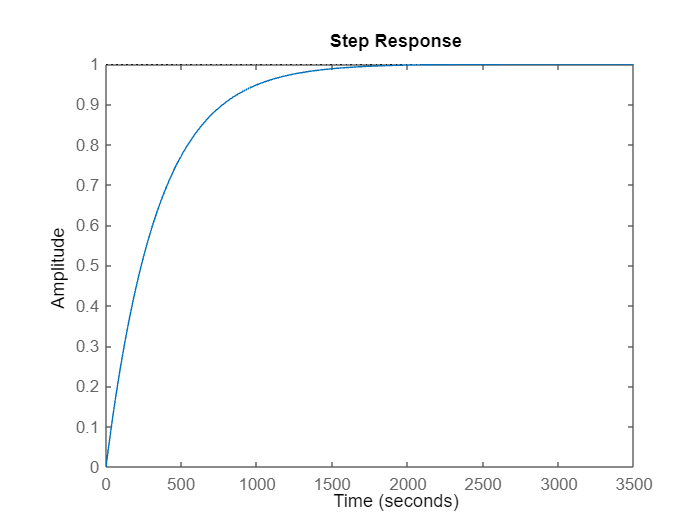

num1 = 0.002965;
den1 = [1 0.002965];
g1 = tf (num1,den1);
step (g1);

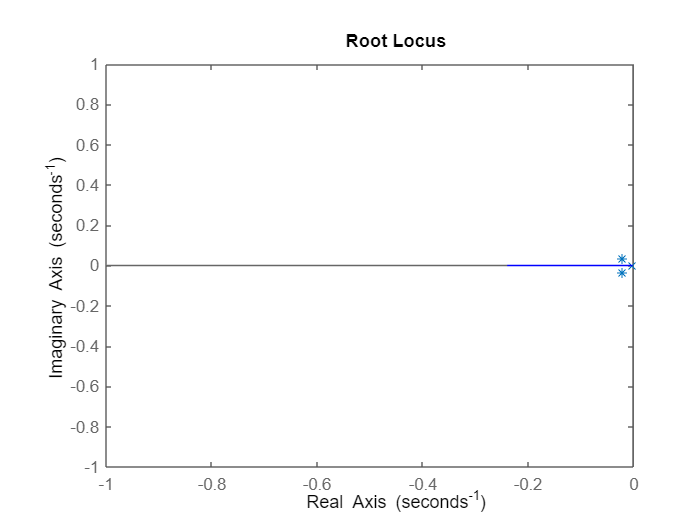

rlocusplot (g1);
xlim([-1, 0]);
ylim([-1, 1]);
hold on
points = [xpoint + ypoint*1i, xpoint - ypoint*1i];
plot(points, '*');
hold off

teta_p = 30;
teta_z = 89.9;
x = ypoint/(tan((30*pi)/180));
p = x + 0.0222

p = 0.0792

y = ypoint/(tan((89.9*pi)/180));
z = 0.0222-y

z = 0.0221

s = -0.0222 + 0.0328j ;
num2 = 0.002965*(s+z);
den2 = (s+p)*(s+0.002965);
%k = abs(den2/num2)


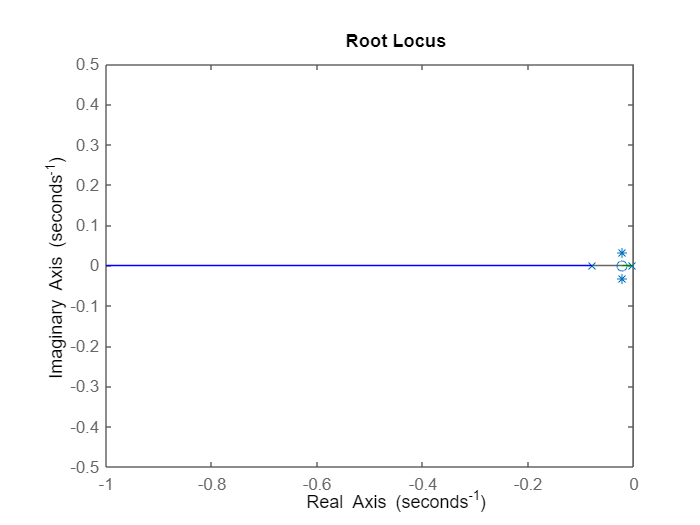

num3 = [k*0.002965 k*0.002965*z];
den3 = [1 0.002965+p 0.002965*p];
g2 = tf(num3,den3);
rlocusplot (g2);
xlim([-1, 0]);
ylim([-0.5, 0.5]);
hold on
points = [xpoint + ypoint*1i, xpoint - ypoint*1i];
plot(points, '*');
hold off

%sisotool(g2);

K_old = 1;
K_new = 1.1;
z2 = -xpoint/10;
p2 = (z2*K_old)/K_new;

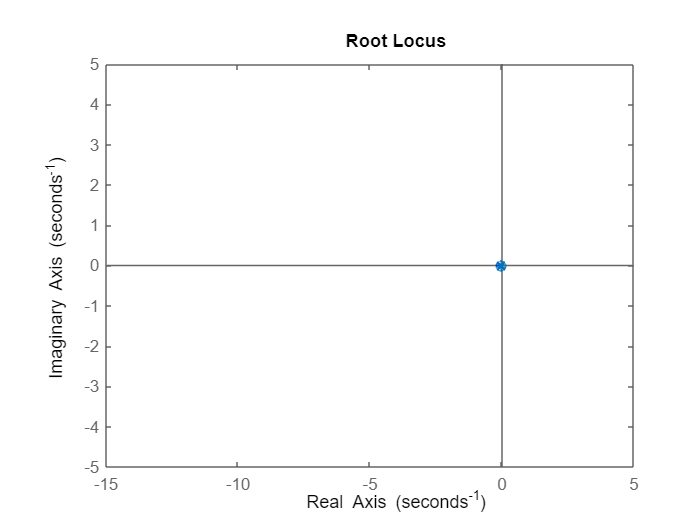

num4 = [0.002965 0.002965*z2];
den4 = [1 0.002965+p2 0.002965*p2];
g3 = tf(num4,den4);


%sisotool(g3)